#  Прием ЧМ стерео сигналов

# Broadcast Receiver

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Введение

В FM Broadcast Transmitter был описан алгоритм формирования частотно-модулированного стерео сигнала. Рассмотрим, как из этого сигнала восстановить информационное сообщение. В первую очередь необходимо снять частотную модуляцию. Для этого можно использовать любой из описанных в demodulation детектор. Из-за простоты реализации мы будем использовать Delay Line Detector.

Частотной демодуляции и получим мультиплексированный сигнал, спектр которого имеет вид:

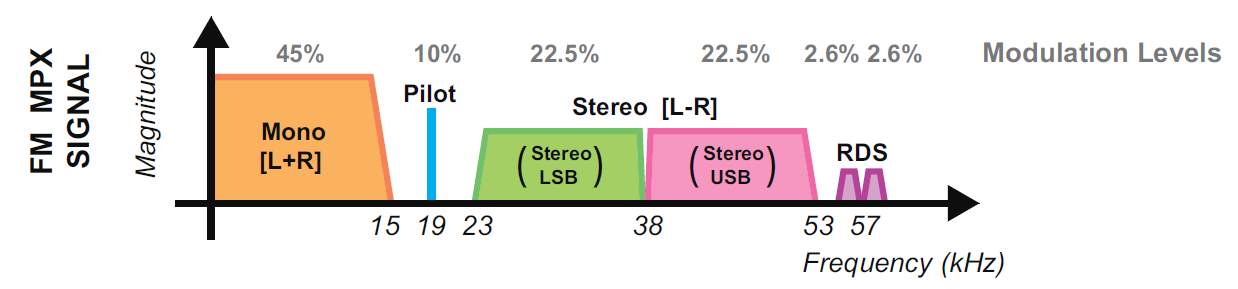

Сначала из сигнала необходимо выделить пилот-сигнал, который потом будет использован для восстановления разностного сигнала. Это можно сделать с помощью полосового фильра, за которым следует PLL. На выходе PLL получим гармоничекий сигнал с частотой 19 kHz. Если сигнал с выхода петлевого фильра PLL умножить на 2 и подать на отдельный NCO, то получим тон с частотой 38 kHz. Частота и фаза этого тона будут совпадать с частотой и фазой несущей разностного сигнала, модулированного с помощью DSB-SC.

С помощью фильтра можно выделить разносный сигнал, а затем перенести его на нулевую частоту, умножая на полученный от PLL тональный сигнал. Суммарный сигнал можно выделить, просто пропустив его через фильтр нижних частот.

Получим суммарный и разностный сигналы, с помощью их сложения и вычитания можно восстановить отдельные дорожки для левого и правого каналов. Схема приемного устройства показана ниже:

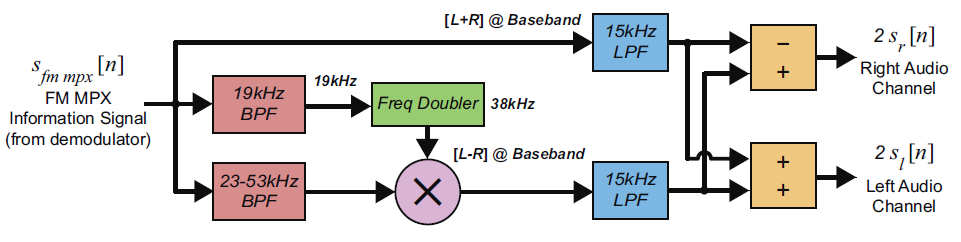

### 2. Реализация приемника стерео сигналов в Matlab

Ниже представлен скрипт, позволяющий прослушивать FM-радио с помощью RTL-SDR. Настройка на нужную радиостанцию выполняется с помощью переменной Fc, которая задает частоту несущей. С помощью полосового фильтра из сигнала удаляются другие радиостанции и он демодулируется с помощью Delay Line Detector. После думодуляции частота дискретизации уменьшается в 5 раз, и мы получаем мультиплексированный сигнал.

Из этого сигнала с помощью полосового фильтра выделяется гармоничекий пилот-сигнал. Чтобы упростить дальнейшие операции, пилот-тон преобразуется в комплексную экспоненту с помощью преобразования Гильберта. Аналитический тональный сигнал (19 kHz) подается на PLL, которая сразу формирует компелксную экспоненту на удвоенной частоте (38 kHz).

С помощью умножения на сопряженную к этой экспоненте и низкочастотной фильтрации из мультиплексированного сигнала выделяется разностный сигнал. Суммарный сигнал также выделяется низкочастотным фильтром с полосой 15 kHz.

Из суммарного и разностного сигналы, с помощью их сложения и вычитания можно полуить отдельные дорожки для левого и правого каналов. После децимации восстановленный стерео сигнал подается на звуковую карту.

clc; clear; close all;
addpath('matlab/broadcast');

Fc = 106.2e6;                % частота несущей в Hz
SignalFs = 1.2e6;            % частота дискретизации RTL-SDR
DemodFs = 120e3;             % частота дискретизации после частотной демодуляции
AudioFs = 48e3;              % частота дискретизации демодулированного аудиосигнала
SignalFrameSize = 512*25;    % количество отсчетов чм-сигнала, получаемых за один раз
AudioAmp = 0.1;              % коэффициент усиления аудиосигнала

% длина фрейма после первой децимации
DemodFrameSize = SignalFrameSize * DemodFs / SignalFs;

% RTL-SDR приемник
SDRRTL = comm.SDRRTLReceiver(...
    'RadioAddress', '0',...
    'CenterFrequency', Fc,...
    'EnableTunerAGC', true,...
    'SampleRate', SignalFs, ...
    'SamplesPerFrame', SignalFrameSize,...
    'OutputDataType', 'double' ...
);

% расчет коэффициентов и создание фильтра нижних частот
Fpass = 110e3;
Fstop = 160e3;
H = Demod_Lowpass_FIR_Coeff(SignalFs, Fpass, Fstop);
DemodFIR = dsp.FIRFilter(H.Numerator);

% задержка на один отсчет
DelayBlock = dsp.Delay;

% фильтр для выделения пилот-сигнала
H = Pilot_Bandpass_FIR_Coeff(DemodFs);
PilotFIR = dsp.FIRFilter(H.Numerator);

% фильтры для выделения стерео-каналов
H = Channel_Lowpass_FIR_Coeff(DemodFs);
SumChannelFIR = dsp.FIRFilter(H.Numerator);
SubChannelFIR = dsp.FIRFilter(H.Numerator);

% PLL для синхронизации по пилот-сигналу
PLL = ComplexPLL( ...
    'SampleFrequency', DemodFs, ...
    'NoiseBandwidth', 100, ...
    'Dampingfactor', 0.7, ...
    'CentralFrequency', 19e3 ...
    );

% объект вычисления преобразования Гильберта
% формирует аналитический сигнал
HilbertTranform = dsp.AnalyticSignal(...
    'FilterOrder', 100 ...
    );

% дециматоры 
DownSampler_1 = dsp.SampleRateConverter(...
    'Bandwidth', 110e3, ...
    'StopbandAttenuation', 80, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', DemodFs ...Audio
    );

DownSampler_2 = dsp.SampleRateConverter(...
    'Bandwidth', 30e3, ...
    'StopbandAttenuation', 80, ...
    'InputSampleRate', DemodFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',DemodFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -DemodFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Demodulated Signal'}, ...
    'SampleIncrement', DemodFs/DemodFrameSize ...
    );

% воспроизведение аудио сигнала
AudioSink = audioDeviceWriter(AudioFs);

% запуск симуляции
while(true)
    % получение отсчетов сигнала и фильтрация
    FmSignalData = SDRRTL();
    FmSignalData = DemodFIR(FmSignalData);
    
    % частотная демодуляция, удаление постоянной составляющей и децимация
    FmSignalDataDelayed = DelayBlock(FmSignalData);
    PhaseDiff = angle(FmSignalData .* conj(FmSignalDataDelayed));
    PhaseDiff = PhaseDiff - mean(PhaseDiff);
    DemodData = DownSampler_1(PhaseDiff);
    
    % вычисление спектров и вывод результатов на график
    SpectrumData = SpecEstimator(DemodData);
    Plotter(SpectrumData);

    % выделение пилот-тона, получение аналитического сигнала и синхронизация  
    PilotData = PilotFIR(DemodData);
    PilotData = HilbertTranform(PilotData);
    [~, PilotData, ~] = PLL(PilotData);

    % выделение суммарного и разностного сигналов
    SumData = SumChannelFIR(DemodData);
    SubData = SubChannelFIR(DemodData .* conj(PilotData));
    SubData = real(SubData);

    % получение левого и правого каналов и децимация
    ChannelData(:,1) = SumData + SubData;
    ChannelData(:,2) = SumData - SubData;
    AudioData = DownSampler_2(ChannelData);
    
    % проигрывание данных
    AudioSink(AudioData * AudioAmp);
  
end

### 3. Реализация приемника стерео сигналов в Simulink

В файле FM_Broadcast_Receiver.slx представлена Simulink-модель, реализующая приемк стерео сигналов. Все преобразования сигнала совпадают с теми, что ранее были описаны в Matlab скрипте.

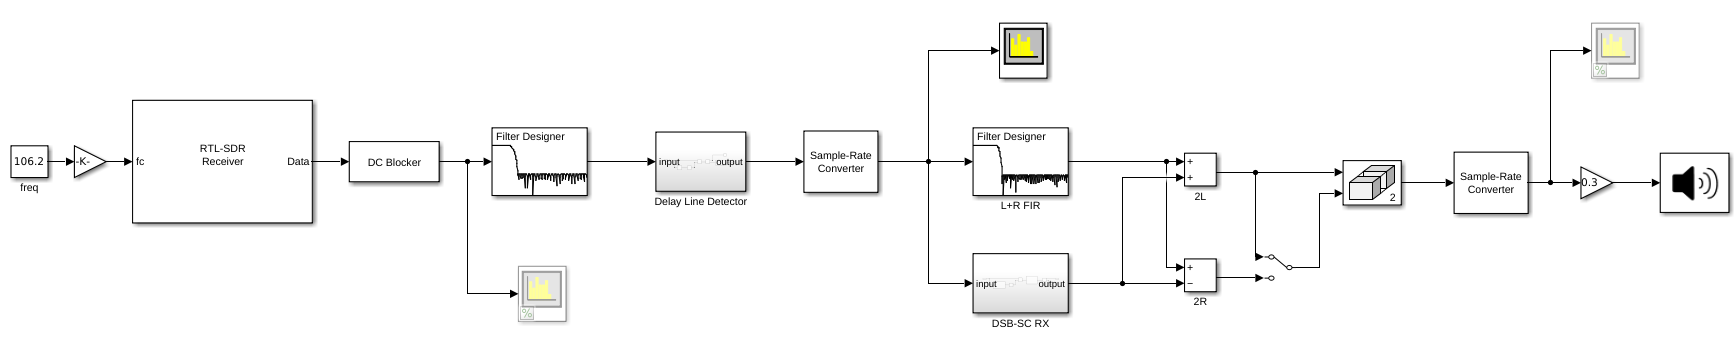

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR